# Regression Analysis (Curve-Fitting)

What is regression (todo)

## Steps:

- Define Problem

- Specify the problem

- Collect Data

- Do Descriptive Analysis

- Estimate Unknown Parameters

- Evaluate Model

- Use Model for Prediction

# Regression Model

## Regression Equation

##                                                 
$$Y=\beta_0 +\beta_1 {\mathit{\mathbf{X}}}_1 +\beta_2 {\mathit{\mathbf{X}}}_2 +\;\ldotp \ldotp \ldotp \beta_{\mathit{\mathbf{n}}} {\mathit{\mathbf{X}}}_{\mathit{\mathbf{n}}} +\epsilon$$


**                    Y = **Dependent Variable

**                    X = **Independent Variable

                    $\epsilon$ = Random Error Term / Residuals

                    $\beta$ = Regression Coefficients

## Linear Regression Models

**Straight Line  :                                **$Y=\beta_0 +\beta_1 {\mathit{\mathbf{X}}}_1 \;$

**Plane :                                             **$Y=\beta_0 +\beta_1 {\mathit{\mathbf{X}}}_1 +\beta_2 {\mathit{\mathbf{X}}}_2$

**Polynomial :                                   **$Y=\beta_0 +\beta_1 {{\mathit{\mathbf{X}}}^3 }_1^{\;} +\beta_2 {{\mathit{\mathbf{X}}}^2 }_2 +\beta_3^{\;} X_3^1$

**Polynomial with Cross Terms :**

# Least Squares

x = [0.8 1.4 2.7 3.8 4.8 4.9];
y = [0.69 1 2.02 2.39 2.34 2.83];

% Solution to AX = Y
% Matrix X = [N sum(x); sum(x) sum(x^2)]
X = [length(x) sum(x); sum(x) sum(x.^2)];
Y = [sum(y) ; sum(x.*y)];
A = X\Y;
plot( x, y, 'o', [0.5 5], A(1)+A(2)*[0.5 5], '--r')

# Goodness of Fit

## Numerical Methods

- SSE (Sum of squares due to errors)

- R- Square 

- Adjusted R-square

- RMSE (Root mean square Error)

## Graphical Methods

- Residual Plots

- Cook's Distance

- Confidence and Prediction Bounds

**Graphical Methods are more beneficial than Numerical Methods**

# Residual Plots

Residuals are plotted against the fitted values

Residuals are symmetric and hace a constant spread.

# Cook's Distance

**A way to identify the points that negatively affect a regression model**

**General Rule: **Observation with a Cook's Distance of more than 3 times mean ($\mu$) is possible outlier.

# Confidence Bounds

**Confidence Interval(CI) **is a type of interval estimate of regression coefficients.

**Confidence Level :** How frequently the observed contains the true parameter if the experiment is repeated.

# Evaluating Goodness of Fit

**For a Good Fit, the desired values are:**

- **SSE - 0**

- **R- Square - I**

- **Adjusted R- square - I**

- **P- value - Value below 0.05 **indicate dependent variables significantly affect independent variables

**Q. Fit a regression to predict the weight of any student given his/her height.**

heights = [63, 63, 66, 69, 69, 71, 71, 72, 73, 75]';
weights = [127, 121, 142, 157, 162, 156, 169, 165, 181, 208]';
table1 = table(heights, weights);
model = fitlm(table1,'weights~heights')
plot(model)
plotResiduals(model,'fitted')
plotDiagnostics(model,'cookd')

**The pair (75, 208) is an outlier and negatively affects the model.**

**Remove it and fit again.**

table1(10,:) = [];
myfit2 = fitlm(table1)
plot(myfit2);
% Predict the values using the model
predict(myfit2,75)
predict(myfit2,0)
predict(myfit2,65)
predict(myfit2,80)

# **Normal Distribution of Grades**

**Q. Distribute the grades (A-F) using randtool command.**

- **1000 samples**

- $\mu$ = 65 (60-70)

- $\sigma$ = 12(11-13)

**USE RANDTOOL in command window to export the data.**

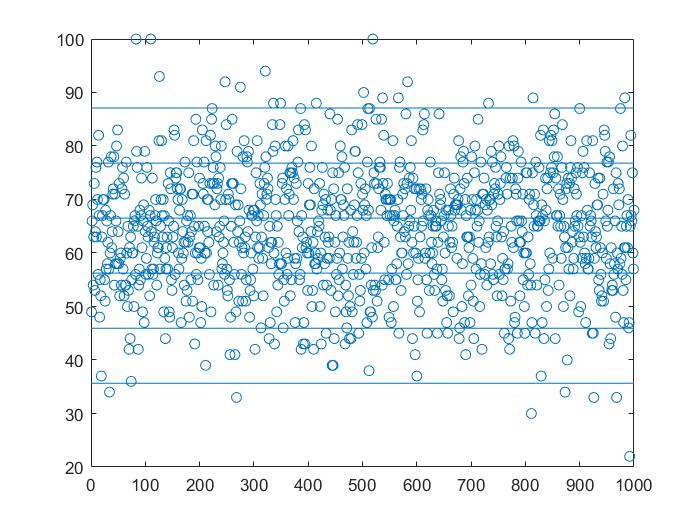

% If marks>100, make them 100 | marks(marks>100)=100
index = marks>100;
marks(index) = 100;
% if marks<5, make them 5
index = marks<5;
marks(index) = 5;
% if marks are fractionals, find their GI
marks = floor(marks);


plot(marks,'o');
% Then import the y-stats from the Data Statistics option
ystats = datastats(marks);

A_Aplus = ystats.mean+(2*ystats.std);
E_F = ystats.mean-(2.5*ystats.std);

if E_F<35
    E_F = 35;
end
div = (A_Aplus-E_F)/5;

D_E = E_F+div;
C_D = E_F+2*div;
B_C = E_F+3*div;
A_B = E_F+4*div;

% refline(m, c)
refline([0 A_Aplus]);
refline([0 E_F]);
refline([0 D_E]);
refline([0 C_D]);
refline([0 B_C]);
refline([0 A_B]);

%Number of students who obtained the respective grade
index = marks>=E_F & marks<D_E;
count_E = length(marks(index))

count_E = 52

% and same for the rest